  clear 


x_moto = [5,0,9,7,1,3,6,8,4,4,6,4,2,4,7,2]

x_moto =      5     0     9     7     1     3     6     8     4     4     6     4     2     4     7     2



K = fix(log2(length(x_moto)))+1

K = 5


L = 2.^[0:K-1]

L =      1     2     4     8    16



x= zeros(1,1000);
x(1:length(x_moto))=x_moto;

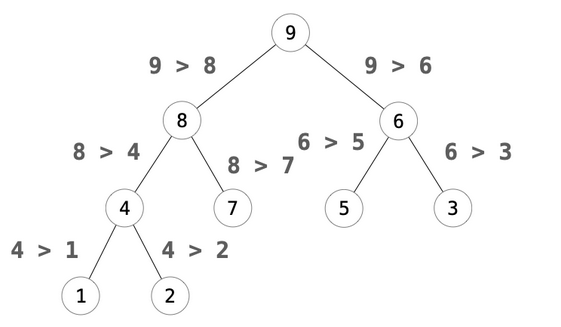



%     if x(L(2)) < x(L(2)+1) % % 左が大きいにする。
%         tmp = x(L(2));
%         x(L(2)) = x(L(2)+1);
%         x(L(2)+1) = tmp;
%     end
%     x
% 
%     if x(L(1)) < x(L(2)) 
%         tmp = x(L(1));
%         x(L(1)) = x(L(2));
%         x(L(2)) = tmp;
%     end
%     x


%     if x(L(3)+0) < x(L(3)+1) % % 左が大きいにする。
%         tmp = x(L(3)+0);
%         x(L(3)+0) = x(L(3)+1);
%         x(L(3)+1) = tmp;
%     end
%     x
% 
%     if x(L(2)) < x(L(3)+0) 
%         tmp = x(L(2));
%         x(L(2)) = x(L(3)+0);
%         x(L(3)+0) = tmp;
%     end
%     x
% 
% 
%         if x(L(3)+2) < x(L(3)+3) % % 左が大きいにする。
%         tmp = x(L(3)+2);
%         x(L(3)+2) = x(L(3)+3);
%         x(L(3)+3) = tmp;
%     end
%     x
% 
%     if x(L(2)) < x(L(3)+2) 
%         tmp = x(L(2)+2);
%         x(L(2)) = x(L(3)+2);
%         x(L(3)+2) = tmp;
%     end
%     x

    

%    for m=0:2
%        n=m+1;
% 
%         if x(L(3)+m) < x(L(3)+n) % % 左が大きいにする。
%             tmp = x(L(3)+m);
%             x(L(3)+m) = x(L(3)+n);
%             x(L(3)+n) = tmp;
%         end
%         x
%     
%         if x(L(2)) < x(L(3)+m) % 上が大きいにする。
%             tmp = x(L(2)+m);
%             x(L(2)) = x(L(3)+m);
%             x(L(3)+m) = tmp;
%         end
% 
%    end
% 
%    x




%   l=3
%    for m=[0,2]
%        n=m+1;
% 
%         if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
%             tmp = x(L(l)+m);
%             x(L(l)+m) = x(L(l)+n);
%             x(L(l)+n) = tmp;
%         end
%         x
%     
%         if x(L(l-1)) < x(L(l)+m) % 上が大きいにする。
%             tmp = x(L(l-1)+m);
%             x(L(l-1)) = x(L(l)+m);
%             x(L(l)+m) = tmp;
%         end
% 
%    end
% 
%    x



%   l=4
%    for m=[0,2,4,8]
%        n=m+1;
% 
%         if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
%             tmp = x(L(l)+m);
%             x(L(l)+m) = x(L(l)+n);
%             x(L(l)+n) = tmp;
%         end
%         x
%     
%         if x(L(l-1)) < x(L(l)+m) % 上が大きいにする。
%             tmp = x(L(l-1)+m);
%             x(L(l-1)) = x(L(l)+m);
%             x(L(l)+m) = tmp;
%         end
% 
%    end




for l=2:length(L)
   M=(1/2)*2^(l-1)-1
   for m=2*[0:M]
       n=m+1;

        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end

        if x(L(l-1)) < x(L(l)+m) % 上が大きいにする。
            tmp = x(L(l-1)+m);
            x(L(l-1)) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end

   end

end

M = 0

M = 1

M = 3

M = 7


x

x =      9     7     0     8     1     6     3     5     4     6     4     4     2     7     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
